# **Pyrolysis Reactor Design: **

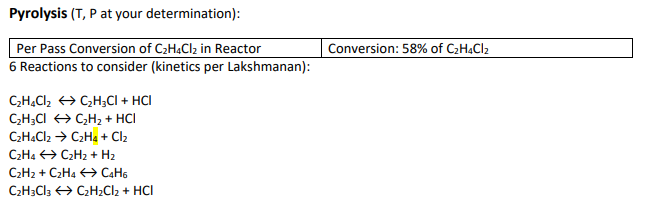

clear; clc; close all;
global Rgas Rgas2

Rgas = 8.314; % kJ/kgmol/K
Rgas2 = 0.082057; % atm*m3/kgmol/K

## Initial Temperature and Pressure:

- Note pressure is constant throughout the lenght of the reactor. $\Delta P=138\;\mathrm{kPa}$ determined from Heuristic 31.

- $T_{\mathrm{out}} =500\;C^o$ given in project description. Heuristic 26 states $T_{\mathrm{min}} =178\;C^o$ in a furnace; thus, $T_{\mathrm{ambient}} =T_{\textrm{out}} -T_{\min } =500+178=678\;C^o$.

% Values from HYSYS Simulation: ( Initial Guess)

Tb = 678 + 273.15;                              % ambient temperature, K --> Heuristic 26
Tk0 = 760;                                      % Initial temperature, K
Tout = 500 + 273.15;                            % Reactor temperature, K --> Project Discription
P0 = 2000;                                      % kPa --> Retrieved from HYSYS Simulation
dP = 138;                                       % Pressure drop along reactor length, kPa 

## Reactor Parameters:

% Look up Overall heat transfer coefficient

Dr = 0.08; % diameter, m ---> GUESSED (Or from HYSYS?)
Nr = 1100; % Number of tubes
Lr = 30; % length, m   ---> GUESSED (Or from HYSYS?)
Ar = pi*Dr^2/4; % x-sectional area, m2
Vr = Ar*Lr; % volume, m3
U  = 200; % 250 W/m^2/K  (Yang et al., 2000)
a  = 4/Dr; % (1/m) heat transfer area

## Flow Rates: 

- % Ethylene	8.54106600834394e-004	8.54106600834394e-004

- % Cl2	4.73757685052407e-019	4.73757685052407e-019

- % 12-ClC2	0.997340332929713	0.997340332929713

- % 112-ClC2	9.02780234726644e-004	9.02780234726644e-004

- % HCl	9.02780234725902e-004	9.02780234725902e-004

- % Oxygen	0.000000000000000	0.000000000000000

- % H2O	0.000000000000000	0.000000000000000

- % CO2	0.000000000000000	0.000000000000000

- % VinylCl	0.000000000000000	0.000000000000000

- % Acetylene	0.000000000000000	0.000000000000000

- % 13-Butadiene	0.000000000000000	0.000000000000000

- Ethylene	0.867658866526508

- Cl2	4.81274884913922E-16

- 12-ClC2	1013.16531445324

- 112-ClC2	0.917104813872446

- HCl	0.917104813871693

- Oxygen	0

- H2O	0

- CO2	0

- VinylCl	0

- Acetylene	0

- 13-Butadiene	0

% Values from HYSYS Simulation:

Fmol_tot = 1016/3600; % kgmol/hr -:  per sec 

% Molar Flow rates: kgmole/hr -: per sec

Fmol_C2H4Cl2 = 1013.1653/3600;            % 12-ClC2
Fmol_C2H3Cl  = 0/3600;                    % Vinyl Chloride
Fmol_HCl     = 0.9171/3600;               % HCl
Fmol_C2H2    = 0;                    % Acetylene
Fmol_C2H4    = 0.8677/3600;               % Ethylene
Fmol_Cl2     = 0/3600;                    % Cl2
Fmol_H2      = 0/3600; % product            H2
Fmol_C4H6    = 0/3600;                    % 13-Butadiene
Fmol_C2H3Cl3 = 0.9171/3600;               % 112-ClC2
Fmol_C2H2Cl2 = 0/3600; % product            C2H2Cl2

## Heats of Reaction Calculations: 

% Assume Cp is constant with temperature.

Values retrieved from [https://www.crct.polymtl.ca/factweb.php](https://www.crct.polymtl.ca/factweb.php) + (Peryy's handbook)

% Linear interpolation:  y = y1 + (y2-y1)/(x2-x1) * (x-x1);

% Heat capacities at Reactor temperature 500 C --> 773.15 K
CpCoeff = [ 3.34E+04	9.48E+04	1.60E+03	5.51E+04	7.41E+02  % C2H4    1
2.92E+04	9.05E+03	2.09E+03	-1.07E+02	1.20E+02          % HCl     2
6.53E+04	1.13E+05	1.74E+03	8.78E+04	7.95E+02          % C2H4Cl2 3
6.66E+04	1.13E+05	1.55E+03	9.72E+04	7.17E+02          % C2H3Cl3 4
4.24E+04	8.74E+04	1.65E+03	6.56E+04	739.07            % C2H3Cl  5
3.20E+04	5.42E+04	1.59E+03	4.33E+04	607.1             % C2H2    6
2.91E+04	9.18E+03	9.49E+02	1.00E+04	4.25E+02          % Cl2     7
2.76E+04	9.56E+03	2.47E+03	3.76E+03	5.68E+02          % H2      8
5.59E+04	1.67E+05	1.53E+03	1.07E+04	6.56E+02          % C4H6    9
];
CpT0_C2H4Cl2 = HtCap0(3,Tout,CpCoeff) * 10^3; % kJ/mol/K --> kJ/kmole/K
CpT0_C2H3Cl  = HtCap0(5,Tout,CpCoeff) * 10^3;
CpT0_HCl     = HtCap0(2,Tout,CpCoeff) * 10^3;
CpT0_C2H2    = HtCap0(6,Tout,CpCoeff) * 10^3;
CpT0_C2H4    = HtCap0(1,Tout,CpCoeff) * 10^3;
CpT0_Cl2     = HtCap0(7,Tout,CpCoeff) * 10^3;
CpT0_H2      = HtCap0(8,Tout,CpCoeff) * 10^3;
CpT0_C4H6    = HtCap0(9,Tout,CpCoeff) * 10^3;
CpT0_C2H3Cl3 = HtCap0(4,Tout,CpCoeff) * 10^3;
CpT0_C2H2Cl2 = 65.061 * 10^(0); % j/mol/K --> kJ/mol/K

% Heat Capacities at refrence temperature 298 K

CpTr_C2H4Cl2 = HtCap0(3,298,CpCoeff) * 10^3; % kJ/mol/K --> kJ/kmole/K
CpTr_C2H3Cl  = HtCap0(5,298,CpCoeff) * 10^3;
CpTr_HCl     = HtCap0(2,298,CpCoeff) * 10^3;
CpTr_C2H2    = HtCap0(6,298,CpCoeff) * 10^3;
CpTr_C2H4    = HtCap0(1,298,CpCoeff) * 10^3;
CpTr_Cl2     = HtCap0(7,298,CpCoeff) * 10^3;
CpTr_H2      = HtCap0(8,298,CpCoeff) * 10^3;
CpTr_C4H6    = HtCap0(9,298,CpCoeff) * 10^3;
CpTr_C2H3Cl3 = HtCap0(4,298,CpCoeff) * 10^3;
CpTr_C2H2Cl2 = 65.061  * 10^(0); % J/mol-K --> kJ/mole-K

% Delta Cp units J/mol --> Cp_r (298) - Cp_r (Tr) + Cp_p (Tr) - Cp_p (298)

% Reactants:

DeltaCp_C2H4Cl2 = (CpT0_C2H4Cl2 - CpTr_C2H4Cl2) ;
DeltaCp_C2H3Cl  = (CpT0_C2H3Cl  - CpTr_C2H3Cl)  ;              % product in rxn 1
DeltaCp_C2H4    = (CpT0_C2H4 - CpTr_C2H4)       ;              % product in rxn 3
DeltaCp_C2H2    = (CpT0_C2H2 - CpTr_C2H2)       ;              % product in rxn 2
DeltaCp_C2H3Cl3 = (CpT0_C2H3Cl3 - CpTr_C2H3Cl3) ;

% Products:

DeltaCp_HCl = (CpT0_HCl - CpTr_HCl) ;
DeltaCp_Cl2 = (CpT0_Cl2 - CpTr_Cl2) ;
DeltaCp_H2  = (CpT0_H2  - CpTr_H2)  ;
DeltaCp_C4H6 = (CpT0_C4H6 - CpTr_C4H6) ;
DeltaCp_C2H2Cl2 = (CpT0_C2H2Cl2)    ; % kJ/kmol-K

% Heats of Formation (Perry's) at 298.15K in J/kmol x 1E-07 --> multiply by 10^4 to get kJ/kmol
Hf_C2H4Cl2 = -12.979 * 10^4;                       % 1,2-Dichloroethane
Hf_C2H3Cl = 2.845    * 10^4;                       % convert to kJ/mol --> kJ/mole
Hf_HCl = -9.231      * 10^4;
Hf_C2H2 = 22.82      * 10^4;
Hf_C2H4 = 5.251      * 10^4;
Hf_Cl2 = 0;
Hf_H2 = 0;
Hf_C4H6 = 16.52      * 10^4;
Hf_C2H3Cl3 = -14.2   * 10^4;
Hf_C2H2Cl2 = 2.427   * 10^3;                       % From Weimer email, kJ/mol --> kJ/kmole

% Heats of Reaction at T = 298.15K

Hr0_1 =- Hf_C2H4Cl2 + (Hf_C2H3Cl + Hf_HCl);     % kJ/mol
Hr0_2 =- Hf_C2H3Cl  + (Hf_C2H2 + Hf_HCl);
Hr0_3 =- Hf_C2H4Cl2 + (Hf_C2H4 + Hf_Cl2);
Hr0_4 =- Hf_C2H4 + (Hf_C2H2 + Hf_H2);
Hr0_5 =- (Hf_C2H2 + Hf_C2H4) + Hf_C4H6;
Hr0_6 =- Hf_C2H3Cl3 + (Hf_C2H2Cl2 + Hf_HCl);


% Heat of reaction at T reactor units J/mol --> Converted to kJ/kgmole
% (iGNORE THIS)

$H_{\mathrm{rxn},j} =H_{f,j} +\int_{298\;C^o }^{T_{\mathrm{Reactor}} \;C^o } C_{p,\mathrm{product}} \;\mathrm{dT}-\int_{298\;C^o }^{T_{\mathrm{Reactor}\;C^o } } C_{p,\mathrm{reactant}} \;\mathrm{dT}$, where $i=\mathrm{reaction}\;\mathrm{number}$.

Hrxn_1 = ( Hr0_1 + ( DeltaCp_C2H3Cl  + DeltaCp_HCl - DeltaCp_C2H4Cl2 ) ) * 10^(0) ; % kJ/mole
Hrxn_2 = ( Hr0_2 + ( DeltaCp_C2H2    + DeltaCp_HCl - DeltaCp_C2H3Cl  ) ) * 10^(0) ;
Hrxn_3 = ( Hr0_3 + ( DeltaCp_C2H4    + DeltaCp_Cl2 - DeltaCp_C2H4Cl2 ) ) * 10^(0) ; % Irriversible Reaction
Hrxn_4 = ( Hr0_4 + ( DeltaCp_C2H2    + DeltaCp_H2  - DeltaCp_C2H4    ) ) * 10^(0) ;
Hrxn_5 = ( Hr0_5 + ( DeltaCp_C4H6                  - sum([ DeltaCp_C2H4 DeltaCp_C2H2 ]) ) ) * 10^(0) ;
Hrxn_6 = ( Hr0_6 + ( DeltaCp_C2H2Cl2 + DeltaCp_HCl - DeltaCp_C2H3Cl3 ) ) * 10^(0) ;

**Note: only reaction 5 is exothermic. **

## Molecular Weights:

MW_C2H4Cl2 = 98.96; % g/mole == kg/kmole
MW_C2H3Cl  = 62.498;
MW_HCl     = 36.458;
MW_C2H2    = 26.04;
MW_C2H4    = 28.05;
MW_Cl2     = 70.90;
MW_H2      = 2.02;
MW_C4H6    = 54.091;
MW_C2H3Cl3 = 133.4;
MW_C2H2Cl2 = 96.95;

## Initial Conditions: 

FeedP = P0/101; % atm
Pout  = FeedP-dP/101;
Y0 = [ Fmol_C2H4Cl2 Fmol_C2H3Cl Fmol_HCl Fmol_C2H2 Fmol_C2H4 Fmol_Cl2 Fmol_H2 Fmol_C4H6 Fmol_C2H3Cl3 Fmol_C2H2Cl2 Tk0 FeedP];
Vspan = linspace(0,Vr,200); % Solution Span

## Anonymous Function:

PYRanon = @(v,y) PyrSimulation(v,y, Fmol_C2H4Cl2, Fmol_C2H3Cl,Fmol_HCl,Fmol_C2H2, Fmol_C2H4, Fmol_Cl2, Fmol_H2, Fmol_C4H6,...
    Fmol_C2H3Cl3, Fmol_C2H2Cl2, Tk0,Fmol_tot, dP, Hrxn_1, Hrxn_2, Hrxn_3, Hrxn_4, Hrxn_5, Hrxn_6, U, a, ...
    CpT0_C2H4Cl2, CpT0_C2H3Cl, CpT0_HCl, CpT0_C2H2, CpT0_C2H4, CpT0_Cl2, CpT0_H2, CpT0_C4H6,CpT0_C2H3Cl3, CpT0_C2H2Cl2,...
     Lr, Tb,Vr, Ar);

% Solve ODEs:
[vsoln, ysoln] = ode23s(PYRanon, Vspan,Y0);

% Unpack Solutions:
MFlowC2H4Cl2 = ysoln(:,1);
MFlowC2H3Cl  = ysoln(:,2);
MFlowHCl     = ysoln(:,3);
MFlowC2H2    = ysoln(:,4);
MFlowC2H4    = ysoln(:,5);
MFlowCl2     = ysoln(:,6);
MFlowH2      = ysoln(:,7);
MFlowC4H6    = ysoln(:,8);
MFlowC2H3Cl3 = ysoln(:,9);
MFlowC2H2Cl2 = ysoln(:,10);
T_reactor    = ysoln(:,11);
P_reactor    = ysoln(:,12);

% Conversion of C2H4Cl2

Conv_R0 = (Fmol_C2H4Cl2 - MFlowC2H4Cl2)/Fmol_C2H4Cl2 * 100 ; % required 58%
disp(Conv_R0(end))

   71.7637



Vflow = 103.0468; % m^3/h --> hysys
disp(Vr/Vflow * 3600) % residence time 

    5.2682



disp(vsoln(end))

    0.1508




K1f = (   10^(13.6) * exp( - 58000/ (1.987 * T_reactor(end) ) ) );
K1b    = (   0.3*10^9 * exp( - 44000/ ( 1.987 * T_reactor(end) ) ) );

K2f = ( 0.5*10^(14) * exp( - 68000/ ( 1.987 * T_reactor(end) ) ) );
K2b =  (  0.37*10^9 * exp( -40000/ (1.987 * T_reactor(end) ) ) );
K1 = K1f/K1b; K2 =K2f/K2b;
Yield = (K1 -K2)/K1

Yield = 0.9998

## Reactor Behavior:

### Temperature Profile:

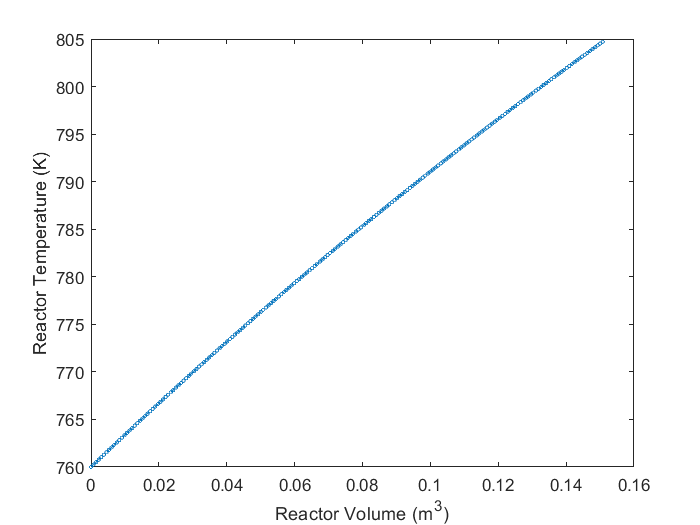

figure('Name','TemperatureProfile') 
plot(vsoln,T_reactor,'--o','MarkerSize',2);
xlabel("Reactor Volume {(m^3)}"); ylabel("Reactor Temperature (K)"); 
grid off 

### Pressure Profile:

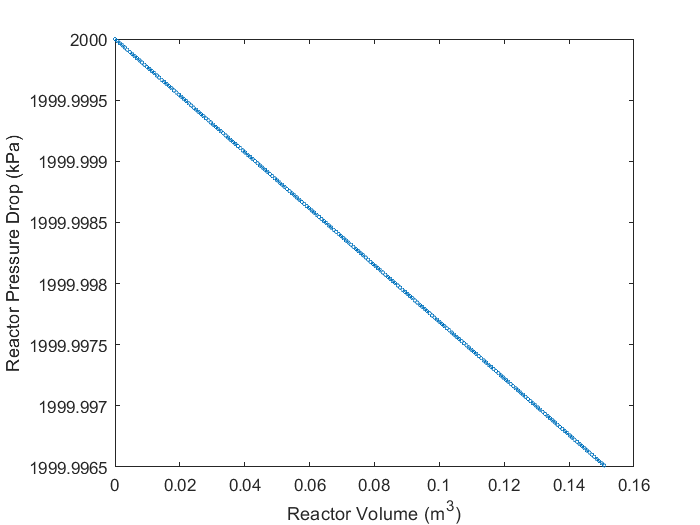

figure('Name','PressureDrop')
plot(vsoln,P_reactor*101,'--o','MarkerSize',2); 
xlabel("Reactor Volume {(m^3)}"); ylabel("Reactor Pressure Drop (kPa)"); 
grid off 

### Species Profile:

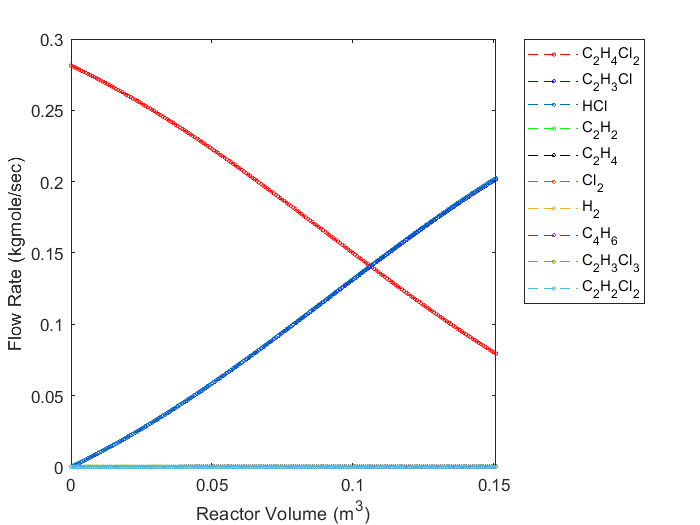

figure('Name','SpeciesProfile')
h= plot(vsoln,MFlowC2H4Cl2,'--or',vsoln,MFlowC2H3Cl,'--ob',vsoln,MFlowHCl,'--o',vsoln,MFlowC2H2,'--og',vsoln,MFlowC2H4,'--ok',vsoln,MFlowCl2,'--o',vsoln,MFlowH2,'--o',...
    vsoln,MFlowC4H6,'--o',vsoln,MFlowC2H3Cl3,'--o',vsoln,MFlowC2H2Cl2,'--o');
xlabel("Reactor Volume {(m^3)}"); ylabel("Flow Rate {({kgmole/sec})}"); 
legend('{C_2H_4Cl_2}','{C_2H_3Cl}','HCl','{C_2H_2}','{C_2H_4}','{Cl_2}','{H_2}','{C_4H_6}','{C_2H_3Cl_3}','{C_2H_2Cl_2}','location','bestoutside');
h(1).MarkerSize = 2; 
h(2).MarkerSize = 2; 
h(3).MarkerSize = 2; 
h(4).MarkerSize = 2; 
h(5).MarkerSize = 2; 
h(6).MarkerSize = 2; 
h(7).MarkerSize = 2; 
h(8).MarkerSize = 2; 
h(9).MarkerSize = 2; 
h(10).MarkerSize = 2; 
grid off 

% ylim([-50 1200])

## Function:

function [outvar] = PyrSimulation(v,y, F_C2H4Cl2, F_C2H3Cl,F_HCl,F_C2H2, F_C2H4, F_Cl2, F_H2, F_C4H6,...
    F_C2H3Cl3, F_C2H2Cl2, FeedT,Feedin_tot, dP, Hrxn_1, Hrxn_2, Hrxn_3, Hrxn_4, Hrxn_5, Hrxn_6, U, a, ...
    CpT0_C2H4Cl2, CpT0_C2H3Cl, CpT0_HCl, CpT0_C2H2, CpT0_C2H4, CpT0_Cl2, CpT0_H2, CpT0_C4H6,CpT0_C2H3Cl3, CpT0_C2H2Cl2, ...
    Lr, Tb, V, Ar)

global Rgas2

% Unpack Dependent Variables:

Fout_C2H4Cl2 = y(1);
Fout_C2H3Cl  = y(2);
Fout_HCl     = y(3);
Fout_C2H2    = y(4);
Fout_C2H4    = y(5);
Fout_Cl2     = y(6);
Fout_H2      = y(7);
Fout_C4H6    = y(8);
Fout_C2H3Cl3 = y(9);
Fout_C2H2Cl2 = y(10);
T            = y(11);
P            = y(12);

% Total Flow out:

Fout_tot = sum([ Fout_C2H4Cl2; Fout_C2H3Cl; Fout_HCl; Fout_C2H4; Fout_C2H2; Fout_Cl2; Fout_H2; Fout_C4H6; Fout_C2H3Cl3; Fout_C2H2Cl2 ]);

% Define Concentrations based on Ideal Gas Model:

C_C2H4Cl2 = Fout_C2H4Cl2 / Fout_tot * P / Rgas2 / T; % kmol/m^3
C_C2H3Cl  = Fout_C2H3Cl / Fout_tot * P / Rgas2 / T;
C_HCl     = Fout_HCl   / Fout_tot * P / Rgas2 / T;
C_C2H2    = Fout_C2H2 / Fout_tot * P / Rgas2 / T;
C_C2H4    = Fout_C2H4 / Fout_tot * P / Rgas2 / T;
C_Cl2     = Fout_Cl2 / Fout_tot * P / Rgas2 / T;
C_H2      = Fout_H2 / Fout_tot * P / Rgas2 / T;

C_C4H6    = Fout_C4H6 / Fout_tot * P / Rgas2 / T;
C_C2H3Cl3 = Fout_C2H3Cl3 / Fout_tot * P / Rgas2 / T;
C_C2H2Cl2 = Fout_C2H2Cl2 / Fout_tot * P / Rgas2 / T;


% C_C2H4Cl2 = Fout_C2H4Cl2 / V; % kmol/m^3-sec
% C_C2H3Cl  = Fout_C2H3Cl / V;
% C_HCl     = Fout_HCl   / V;
% C_C2H2    = Fout_C2H2 / V;
% C_C2H4    = Fout_C2H4 / V;
% C_Cl2     = Fout_Cl2 / V;
% C_H2      = Fout_H2 / V;
% 
% C_C4H6    = Fout_C4H6 / V;
% C_C2H3Cl3 = Fout_C2H3Cl3 / V;
% C_C2H2Cl2 = Fout_C2H2Cl2 / V;

### Reaction Kinetics: (Lakshmanan et al., 1999)


K1f = (   10^(13.6) * exp( - 58000/ (1.987 * T ) ) );
K1b    = (   0.3*10^9 * exp( - 44000/ ( 1.987 * T ) ) );

K2f = ( 0.5*10^(14) * exp( - 68000/ ( 1.987 * T ) ) );
K2b =  (  0.37*10^9 * exp( -40000/ (1.987 * T ) ) );

K3 =       10^(13) * exp( - 72000 / (1.987 * T ) );

K4f = ( 0.1*10^(15) * exp( - 82000/ (1.987 * T ) ) );
K4b = (   0.8*10^9 * exp( - 38000/ (1.987 * T ) ) );

K5f = (   0.15*10^9 * exp( - 32000/ (1.987 * T ) ) );
K5b =  ( 0.5*10^(13) * exp( - 73000/ (1.987 * T ) ) );

K6f = (  0.2*10^(14) * exp( - 58000/ (1.987 * T ) ) );
K6b = (    0.3*10^9 * exp ( - 44000/ (1.987 * T ) ) ); % K6 is K18 in Lakshmanan paper

% Reaction Rates: ---> Kmole/m^3/sec --> kmole/m^3/hr

r1f = (K1f * C_C2H4Cl2)       * 3600;
r1b = K1b * C_C2H3Cl * C_HCl  * 3600;

r2f = K2f * C_C2H3Cl          * 3600;
r2b = K2b * C_C2H2 * C_HCl    * 3600;

r3  = K3 * C_C2H4Cl2          * 3600;

r4f = K4f * C_C2H4            * 3600;
r4b = K4b * C_C2H2 * C_H2     * 3600;

r5f = K5f * C_C2H2 * C_C2H4   * 3600;
r5b = K5b * C_C4H6            * 3600;

r6f = K6f * C_C2H3Cl3         * 3600;
r6b = K6b * C_C2H2Cl2 * C_HCl * 3600;

% r1 = (K1f/K1b * C_C2H4Cl2) * 3600; 
% r2 = (K2f/K2b * C_C2H3Cl)  * 3600; 
% r3 = (K3      * C_C2H3Cl)  * 3600; 
% r4 = (K4f/K4b * C_C2H2)    * 3600; 
% r5 = (K5f/K5b * C_C2H2 * C_C2H4)  * 3600; 
% r6 = (K6b/K6b * C_C2H3Cl3)        * 3600; % kmol/m^3-hr

### Differential Mole Balance: 


$$\frac{\mathrm{d}}{{\mathrm{dV}}_R }F_i =\sum_{j=1,k=1}^N {\nu_{k\;} *\;r}_{f,b,j}$$
 

Multiplied by surface area of reactor. 

outvar(1) = (r1b -r1f - r3);                              % C2H4Cl2
outvar(2) = (r1f -r1b -r2f + r2b) ;                       % C2H3Cl
outvar(3) = (r1f -r1b -r2b + r2f + r6f - r6b) ;           % HCl
outvar(4) = (r2f -r2b  + r4f -r4b - r5f + r5b) ;          % C2H2
outvar(5) = (r3 - r4b + r4f - r5f + r5b) ;                % C2H4
outvar(6) = r3 ;                                          % Cl2
outvar(7) = (r4f- r4b) ;                                  % H2
outvar(8) = (r5f-r5b) ;                                   % C4H6
outvar(9) = (-r6f + r6b);                                 % C2H3Cl3
outvar(10)= (r6f - r6b) ;                                 % C2H2Cl2

% outvar(1) = r1 - r3;                                 % C2H4Cl2
% outvar(2) = r1-r2;                                   % C2H3Cl
% outvar(3) = r1 + r2 + r6;                            % HCl
% outvar(4) = r2 + r4 - r5;                            % C2H2
% outvar(5) = r3 - r4 - r5;                            % C2H4
% outvar(6) = r3;                                      % Cl2
% outvar(7) = r4;                                      % H2
% outvar(8) = r5;                                      % C4H6
% outvar(9) = -r6;                                     % C2H3Cl3
% outvar(10)= r6;                                      % C2H2Cl2

### Thermal Energy Balance: 

outvar(11) =  ( -( Hrxn_1*(r1f-r1b) + Hrxn_2*(r2f-r2b) + Hrxn_3*(r3) + Hrxn_4*(r4f-r4b) + Hrxn_5*(r5f-r5b) + Hrxn_6*(r6f-r6b) ) - U*a*(T-Tb) *3.6) ...
    ... 
    / (Fout_C2H4Cl2 * CpT0_C2H4Cl2 + Fout_C2H3Cl * CpT0_C2H3Cl + Fout_HCl * CpT0_HCl + Fout_C2H2 * CpT0_C2H2 + Fout_C2H4 * CpT0_C2H4 + ...
    ...
       Fout_Cl2 * CpT0_Cl2 + Fout_H2 * CpT0_H2 + Fout_C4H6 * CpT0_C4H6 + Fout_C2H3Cl3 * CpT0_C2H3Cl3 + Fout_C2H2Cl2 * CpT0_C2H2Cl2);

% outvar(11) = -( -( Hrxn_1*(r1) + Hrxn_2*(r2) + Hrxn_3*(r3) + Hrxn_4*(r4) + Hrxn_5*(r5) + Hrxn_6*(r6) ) - U*a*(T-Tb) *3.6) ...
%     ... 
%     / (Fout_C2H4Cl2 * CpT0_C2H4Cl2 + Fout_C2H3Cl * CpT0_C2H3Cl + Fout_HCl * CpT0_HCl + Fout_C2H2 * CpT0_C2H2 + Fout_C2H4 * CpT0_C2H4 + ...
%     ...
%        Fout_Cl2 * CpT0_Cl2 + Fout_H2 * CpT0_H2 + Fout_C4H6 * CpT0_C4H6 + Fout_C2H3Cl3 * CpT0_C2H3Cl3 + Fout_C2H2Cl2 * CpT0_C2H2Cl2);

###  Pressure Drop:


$$\frac{\mathrm{d}}{{\textrm{dV}}_R }P=\Delta P$$


outvar(12) = -dP/101/Lr*Ar;

### Output:

outvar = outvar';
end

## Heat Capacity Function:

function Cp0 = HtCap0(component,T,CpCoef)

a = CpCoef(component,1);
b = CpCoef(component,2);
c = CpCoef(component,3);
d = CpCoef(component,4);
e = CpCoef(component,5);

% TK = T + 273.15;
% TK1 = TK/1000;

Cp0 = ( a*T + 4*b*c^2/(2*c*exp(2*c/T)-2*c) + 4*d*e^2/(2*e*exp(2*e/T)+2*e) ) /10^6; 

end 
        

## Cited Work:

`J. Yang, C. Malendoma, C. Roy,`

`Determination of the Overall Heat Transfer Coefficient in a Vacuum Pyrolysis Moving and Stirred Bed Reactor,`

`Chemical Engineering Research and Design,`

`Volume 78, Issue 4,`

`2000,`

`Pages 633-642,`